%LQR TEORIA
clc; clear all; close all;
A = [0 1; -2 -3];
B = [0 1]';
C = [1 0]

C =      1     0


D = 0

D = 0

Q1 = [5 0; 0 5];
Q2 = [100 0; 0 5];
R = [1];

K1 = lqr(A,B,Q1,R)

K1 =     1.0000    1.0000


K2 = lqr(A,B,Q2,R)

K2 =     8.1980    2.5133



ACL1 = (A-B*K1);
ACL2 = (A-B*K2);


%%Visualizar la primera varible

Gss1 = ss(ACL1,0*B,C,D)

Gss1 =
 
  A = 
       x1  x2
   x1   0   1
   x2  -3  -4
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


Gss2 = ss(ACL2,0*B,C,D)

Gss2 =
 
  A = 
           x1      x2
   x1       0       1
   x2   -10.2  -5.513
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


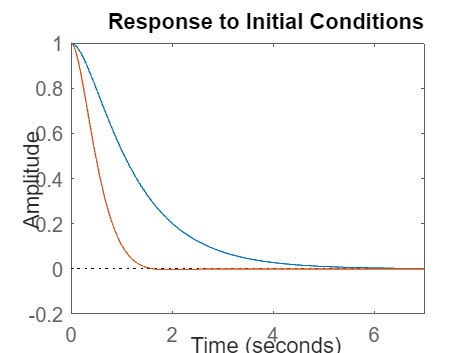


x0 = [ 1 0]';
initial(Gss1,x0); hold on;
initial(Gss2,x0)

A = [0 1, -4 -4];
B = eye(2);
C =[1 0; 0 1];


